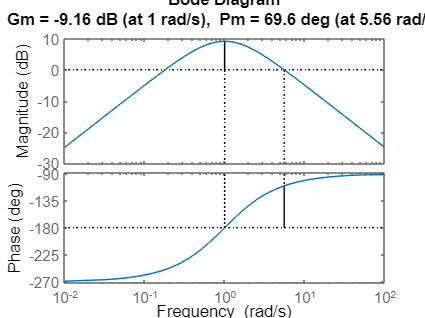

% system
A = [1 1; 0 1];
B = [0; 1];
C = [1 0];

% LQR control
q = 10;
F = (2 + sqrt(4+q))*[1 1];

% Open Loop Transfer Function for LQR, q>0
s = tf('s');
L_t = F*(s*eye(2)-A)^-1*B;
margin(L_t)

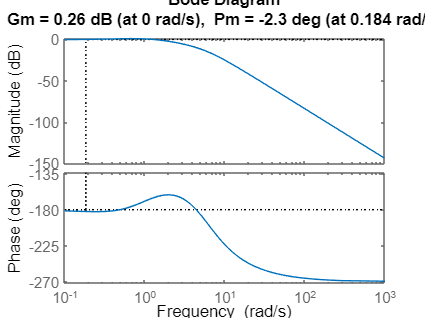

% LQG DESIGN
sigma = 10;
K = (2 + sqrt(4+sigma))*[1;1];
L_o = F*(s*eye(2)-A+B*F+K*C)^-1*K*C*(s*eye(2)-A)^-1*B;
margin(L_o)

% solve ARE (gives same result as F above)
Q = q*[1; 1]*[1 1];
P = icare(A,[],Q,[],[],[],-B*B');
F = B'*P;